GPU issue check it on UV pc

load displaySequence.mat

sig=testData{1,1}

sig =    -0.0184   -0.0184   -0.0184   -0.0180   -0.0150   -0.0108   -0.0062    0.0003    0.0098    0.0178    0.0251    0.0342    0.0426    0.0487    0.0525    0.0541    0.0537    0.0522    0.0468    0.0404    0.0358    0.0308    0.0232    0.0171    0.0122    0.0072    0.0011   -0.0042   -0.0084   -0.0107   -0.0137   -0.0168   -0.0187   -0.0191   -0.0194   -0.0202   -0.0210   -0.0202   -0.0206   -0.0225   -0.0236   -0.0228   -0.0225   -0.0244   -0.0259   -0.0263   -0.0259   -0.0278   -0.0282   -0.0285


label=testData{1,2};
sig=sig(1:1000)

sig =    -0.0184   -0.0184   -0.0184   -0.0180   -0.0150   -0.0108   -0.0062    0.0003    0.0098    0.0178    0.0251    0.0342    0.0426    0.0487    0.0525    0.0541    0.0537    0.0522    0.0468    0.0404    0.0358    0.0308    0.0232    0.0171    0.0122    0.0072    0.0011   -0.0042   -0.0084   -0.0107   -0.0137   -0.0168   -0.0187   -0.0191   -0.0194   -0.0202   -0.0210   -0.0202   -0.0206   -0.0225   -0.0236   -0.0228   -0.0225   -0.0244   -0.0259   -0.0263   -0.0259   -0.0278   -0.0282   -0.0285


label=label(1:1000)

label = 1×1000 categorical array
     n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a      n/a     



X = sig;
classes = categories(label)

classes = 4×1 cell array
    {'n/a'}
    {'P'  }
    {'QRS'}
    {'T'  }



naSig=nan(size(sig))

naSig =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


PSig=naSig;
QRSSig=naSig;
TSig=naSig

TSig =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


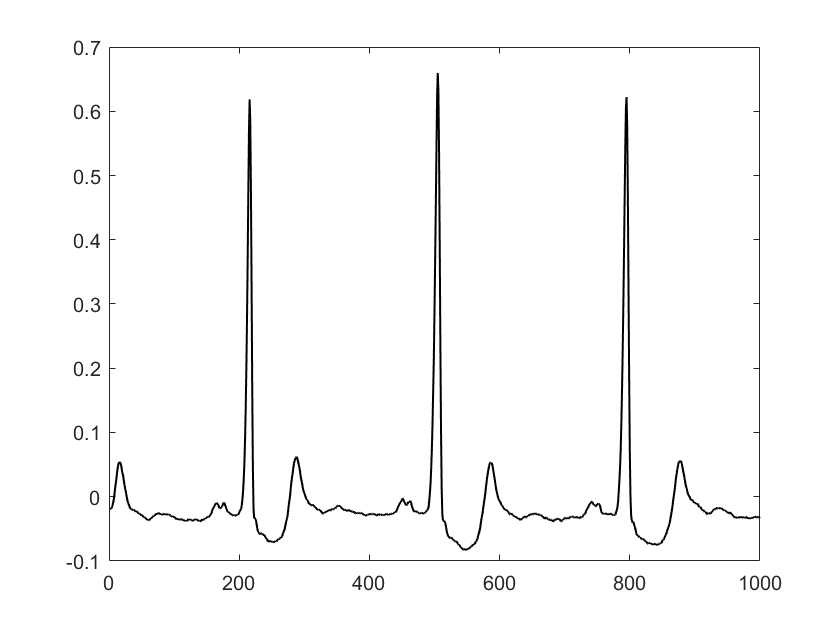


for i=1:length(sig)
  if label(i)=='n/a'
    naSig(i)=X(i);
  elseif label(i)=='P'
    PSig(i)=X(i);
  elseif label(i)=='QRS'
    QRSSig(i)=[X(i) X(i+1)];
  elseif label(i)=='T'
    TSig(i)=X(i);
  end
end

Sig1=naSig;
Sig2=PSig;
Sig3=QRSSig;
Sig4=TSig;

Sig = [Sig1;Sig2;Sig3;Sig4];                                            % Concatenate
Sigfm = fillmissing(Sig, 'linear', 'EndValues','nearest');              % Fill NaN Values
figure
plot(Sigfm(1,:), 'k', 'LineWidth',1)


% figure
% 
% lineWidth=2

% plot(naSig,'LineWidth',lineWidth,'Color',[1 0.76 0])
% hold on
% plot(PSig,'r','LineWidth',lineWidth)
% hold on
% plot(QRSSig,'g','LineWidth',lineWidth)
% hold on
% plot(TSig,'b','LineWidth',lineWidth)
% hold off
% 
% 
% Color1=[[ones(16,1);zeros(32,1);ones(16,1)],[zeros(16,1);ones(16,1);zeros(16,1);ones(16,1)*0.76],[zeros(32,1);ones(16,1);zeros(16,1)]];
% colormap(Color1)
% c=colorbar('Ticks',[0.125,0.375,0.625,0.875],...
%          'TickLabels',{'N/A','P','QRS','T'},"Direction","reverse")
